clear all; close all; clc

syms x1 x2 x3 x4  u
% parametros del sistema
ma=0.6; % masa brazo [kg]
mp=0.2; % masa pendulo [kg]
la=1.1600e-1; % largo del brazo [m]
lp=3.0001e-1; % largo del pendulo [m]
j0=(ma*la^2)/3; %inercia brazo [kg m^2]
g=9.8;  % gravedad [m/s^-2]
j1=(mp*lp^2)/3; % inercia pendulo [kg m^2]

T=0.05;% tiempo de muestreo

#### **Nonlinear Model**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% x1: angulo del brazo (\phi)
% x2: velocidad angular del brazo (\dot\phi)
% x3: angulo del pendulo (\theta)
% x4: velocidad angular del pendulo (\dot\theta)
% u: torque del motor 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% sistema no lineal pendulo
a1=((ma+mp)/3)*la^2;  %alfa
a2=(mp*lp^2)/3;       %beta
a3=(mp*la*lp)/2;      %lambda
a4=(mp*g*lp)/2;       %delta
den=((a1*a2)-a3^2)+((a2^2+a3^2)*sin(x3)^2);
% campo vectorial
f1=x2;
f2=((a2*a3*(sin(x3)^2-1)*sin(x3)*x2^2)-...
    (2*a2^2*cos(x3)*sin(x3)*x2*x4)+(a2*a3*sin(x3)*x4^2)-...
    (a3*a4*cos(x3)*sin(x3))+(a2*u))/den;
f3=x4;
f4=((a2*(a1+a2*sin(x3)^2)*cos(x3)*sin(x3)*x2^2)+...
    (2*a2*a3*(1-sin(x3)^2)*sin(x3)*x2*x4)-...
    (a3^2*cos(x3)*sin(x3)*x4^2)+(a4*(a1+a2*sin(x3)^2)*sin(x3))-...
    (a3*cos(x3)*u))/den;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Punto de operación para linealización del sistema
ref=0;
x1ss=0;
x2ss=0;
x3ss=ref;
x4ss=0;
uss=(3*g*la*mp*sin(2*ref))/8;
As=[diff(f1,x1) diff(f1,x2) diff(f1,x3) diff(f1,x4);...
    diff(f2,x1) diff(f2,x2) diff(f2,x3) diff(f2,x4);...
    diff(f3,x1) diff(f3,x2) diff(f3,x3) diff(f3,x4);...
    diff(f4,x1) diff(f4,x2) diff(f4,x3) diff(f4,x4)];
A=double(subs(As,[x1 x2 x3 x4 u],[x1ss x2ss x3ss x4ss uss]));
Bs=[diff(f1,u);diff(f2,u);diff(f3,u);diff(f4,u)];
B=double(subs(Bs,[x1 x2 x3 x4 u],[x1ss x2ss x3ss x4ss uss]));
%C=[1 0 0 0;0 0 1 0];
%D=[0;0];
C=[1 0 0 0];
D=[0];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% discretización del sistema
PI=ss(A,B,C,D);
sistemad=c2d(PI,T,'zoh');
[AD,BD,CD,DD]=ssdata(sistemad);
AAD=[AD zeros(4,1);-C 1];
BAD=[B;0];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%CONTROLADOR LQR
Q=[50 0 0 0;0 60 0 0; 0 0 0 0; 0 0 0 0]; 
QAD=diag([10,0,1,0,1]);
%Q=[1 0 0 0;0 1 0 0; 0 0 1 0; 0 0 0 1];
%Q=[20 0 0 0;0 1000 0 0; 0 0 10 0; 0 0 0 100];
R=1;
%R=50;
R=0.1;
R1=100;
[Kd,Po,ee]=dlqr(AD,BD,Q,R);
[KAd,Po,ee]=dlqr(AAD,BAD,QAD,R);
Aa=[A zeros(4,1);-C 0];
Ba=[B;0];

Qa=diag([0 0 1 0 0.01]);
Ra=10000;
Ka=lqr(Aa,Ba,Qa,Ra);
K=Ka

K =    -0.0033   -0.0053   -0.6893   -0.0700    0.0010


%% Control pendulo de Furuta en CoppeliaSim
% Se recomienda que sea en un archivo .m y no en un liveScript
% por la velocidad de ejecución
% A. Pantoja, Departamento de Electrónica, Universidad de Nariño
clear estados control controlmed
%clear all
close all
%% Inicialización de objeto CoppeliaSim y sincronización con planta 
vrep=remApi('remoteApi');

Note: always make sure you use the corresponding remoteApi library
(i.e. 32bit Matlab will not work with 64bit remoteApi, and vice-versa)


vrep.simxFinish(-1);
clientID=vrep.simxStart('127.0.0.1',19997,true,true,5000,5)

clientID = 0

r = 180*pi/180; 
re= [];
ban = 0;
ban2 = 0;
b = 0;
sws = [];
%% Parámetros del controlador Swing-up
params.mp = mp;
params.lp = lp;
params.g = g;
params.k = 2.0;
xgain = 0.9;
if (clientID>-1)
    disp('connected to remote API Server');
    vrep.simxSynchronous(clientID,false);    % modo sincronización
    % Obtencion de handles de los objetos en la simulación 
    [~,motor]=vrep.simxGetObjectHandle(clientID,'motor',vrep.simx_opmode_blocking); %motor - pos brazo
    [~,sensor1]=vrep.simxGetObjectHandle(clientID,'Potenciometro',vrep.simx_opmode_blocking); %sensor pos péndulo
    [~,sensorvb]=vrep.simxGetObjectHandle(clientID,'rotating',vrep.simx_opmode_blocking); %sensor vel brazo
    [~,sensorvp]=vrep.simxGetObjectHandle(clientID,'pendulum',vrep.simx_opmode_blocking);%sensor vel pendulo
    % Primera lectura de sensores modo streaming
    [~,angb]=vrep.simxGetJointPosition(clientID,motor,vrep.simx_opmode_streaming);
    [~,angp]=vrep.simxGetJointPosition(clientID,sensor1,vrep.simx_opmode_streaming);
    [~,~,angularb]=vrep.simxGetObjectVelocity(clientID,sensorvb,vrep.simx_opmode_streaming);
    [~,~,angularp]=vrep.simxGetObjectVelocity(clientID,sensorvp,vrep.simx_opmode_streaming);
    [~,torqm]=vrep.simxGetJointForce(clientID,motor,vrep.simx_opmode_streaming);
    vrep.simxPauseSimulation(clientID,vrep.simx_opmode_oneshot);    %pausa simulación
    pause(2);
 %% Inicialización de variables   
    % refv=[200*pi/180 180*pi/180 100*pi/180]; % Referencias
    % ref=refv(1);
    %ref=90*pi/180;
    Tsim=70;            % Tiempo total de la simulación
    Ts=0.1;               % Periodo de muestreo
    Ns=round(Tsim/Ts);  % Número de periodos de muestreo que tendrá la simulación.
    e_ant=0;
    int_err=0;
 %% Main Control Cycle
    vrep.simxStartSimulation(clientID,vrep.simx_opmode_oneshot);
     for i=1:Ns
             tic % Inicia conteo de tiempo para asegugar muestreo
             %vrep.simxStartSimulation(clientID,vrep.simx_opmode_oneshot);
             %vrep.simxSynchronousTrigger(clientID);
         % letura de estados: x1=pos_brazo[rad], x2=pos_pend[rad], x3=vel_brazo[rad/s], x4=vel_pend[rad/s]
             [~,angb]=vrep.simxGetJointPosition(clientID,motor,vrep.simx_opmode_buffer); 
             g(i) = angb;
             angb = angb-floor(angb/(2*pi))*2*pi; % Lectura de 0 a 2*pi sin saltos por periodicidad
             
             [~,angp]=vrep.simxGetJointPosition(clientID,sensor1,vrep.simx_opmode_buffer);
             [~,~,angularb]=vrep.simxGetObjectVelocity(clientID,sensorvb,vrep.simx_opmode_buffer);
             [~,~,angularp]=vrep.simxGetObjectVelocity(clientID,sensorvp,vrep.simx_opmode_buffer);
             [~,torqm]=vrep.simxGetJointForce(clientID,motor,vrep.simx_opmode_buffer);
             
             % if angularb < -1000
             %    b = 1;
             % end
             % if angularb > 1000
             %    b = 0;
             % end
             % if b == 1
             %     angb = angb-2*pi;
             % end
             % Estados medidos en un vector
             x=[angb; angularb(3); angp; angularp(1)]; % estados medidos
            % Aproximacion trapezoidal de la integral de error
             e_act=r-angb; %error angulo del brazo
            
            % Cálculo del torque de control
            y = x(1);
            re(i) = r;   
            % Ganancias interpoladas según el ángulo del brazo (y)
        
            hp(i) = abs(angp-floor(angp/(2*pi))*2*pi);
            if abs(angp-floor(angp/(2*pi))*2*pi) < deg2rad(15) || abs(angp-floor(angp/(2*pi))*2*pi) > deg2rad(345)  && abs(angularp(1)) < deg2rad(100) %&& angb >  deg2rad(50) 
                if ban == 0;
                    r = angb; %deg2rad(50);
                    ban = 1;
                    xgain = 1;
                    ki = 1;
                end
                
                ki = ki+1;
                if ki == 60
                    ban2 = 1;
                    xgain = 0.7;
                end
                % Salida medida: ángulo del brazo (phi)
                 e = r - y;              % Error
                 int_err = int_err + Ts * e;  % Integrador
                 u_c = -xgain*K * [x; int_err];
                 sw = 1;
                 u_c = min(u_c, 0.8);
                 u_c = max(u_c, -0.8);
            else
                 ban = 0;
                 ban2 = 0;
                 u_c = 0.7*swing_up_energy_controller(x, params);
                 %u_c = 0.3*cos(i*0.25);
                 int_err = 0; % Resetear el integrador
                 sw = 0;
             end

            % Aplicación de torque a motor en CoppeliaSim
             if u_c>0
                vel=99; torqap=u_c;
             else
                vel=-99; torqap=-u_c;
             end
             vrep.simxSetJointForce(clientID,motor,torqap,vrep.simx_opmode_blocking);
             vrep.simxSetJointTargetVelocity(clientID,motor,vel,vrep.simx_opmode_blocking);
            % Almacenamiento de vectores y actualización de memoria
            sws(i) =sw;
            e_ant=e_act;
            control(i)=u_c;
            controlmed(i)=torqm;
            %control(i)=vf;
            estados(i,:)=x;

            % Cambio de referencia
            if ban2 == 1
                if i==round(30/Ts)
                    r=140*pi/180;
                elseif i==round(45/Ts)
                    r=50*pi/180;
                end
            end
            toc
            pause(max(Ts-toc, 0));  % Espera el tiempo para garantizar muestreo uniforme      
     end 
    vrep.simxStopSimulation(clientID,vrep.simx_opmode_blocking); % para simulación
    vrep.simxFinish(-1);
end

connected to remote API Server


Elapsed time is 0.164478 seconds.
Elapsed time is 0.087497 seconds.
Elapsed time is 0.090971 seconds.
Elapsed time is 0.093462 seconds.
Elapsed time is 0.092311 seconds.
Elapsed time is 0.091907 seconds.
Elapsed time is 0.093182 seconds.
Elapsed time is 0.094197 seconds.
Elapsed time is 0.094370 seconds.
Elapsed time is 0.095095 seconds.
Elapsed time is 0.091967 seconds.
Elapsed time is 0.092876 seconds.
Elapsed time is 0.086787 seconds.
Elapsed time is 0.092020 seconds.
Elapsed time is 0.093710 seconds.
Elapsed time is 0.093048 seconds.
Elapsed time is 0.094024 seconds.
Elapsed time is 0.094234 seconds.
Elapsed time is 0.093142 seconds.
Elapsed time is 0.091043 seconds.
Elapsed time is 0.093511 seconds.
Elapsed time is 0.093129 seconds.
Elapsed time is 0.139237 seconds.
Elapsed time is 0.089884 seconds.
Elapsed time is 0.092223 seconds.
Elapsed time is 0.092321 seconds.
Elapsed time is 0.091929 seconds.
Elapsed time is 0.092057 seconds.
Elapsed time is 0.093134 seconds.
Elapsed time i

vrep.delete();

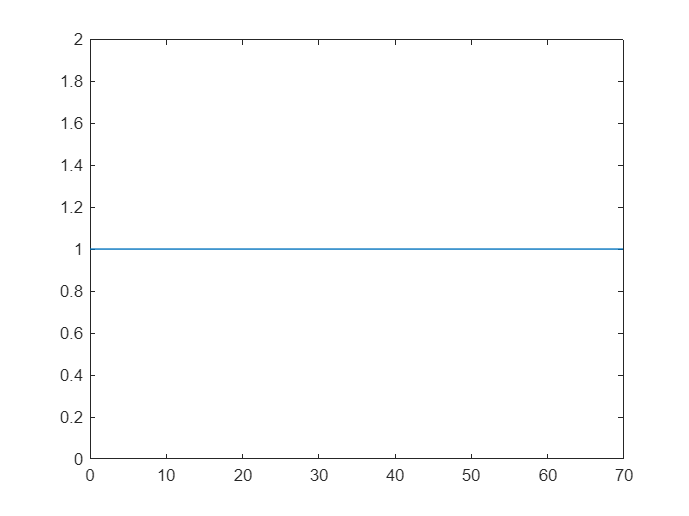

tdisc=0:Ts:Ns*Ts-Ts;
figure;
plot(tdisc, sws)

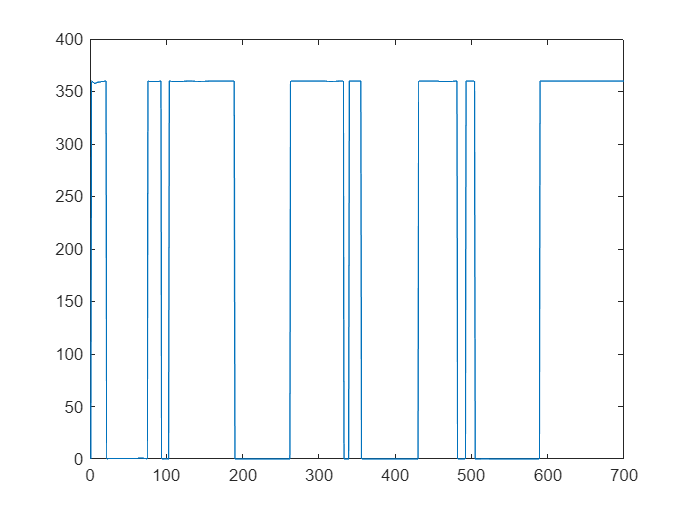

figure;
plot(hp*180/pi)

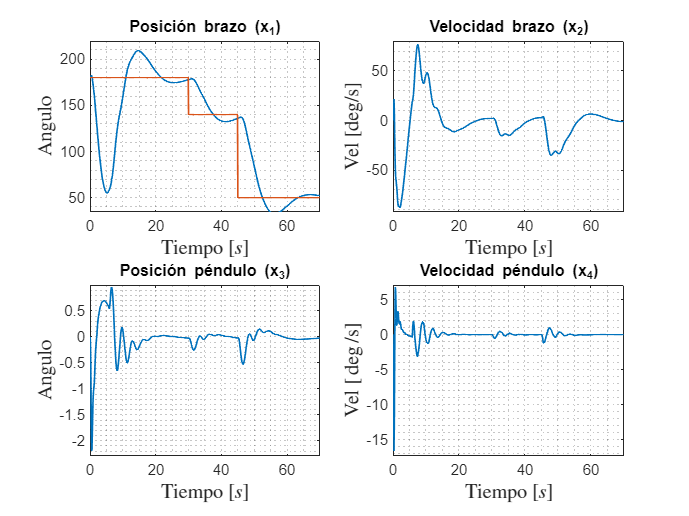


figure
subplot(2,2,1);
plot(tdisc,estados(:,1)*180/pi, 'LineWidth', 1);
hold on;
plot(tdisc, re*180/pi, 'LineWidth', 1);
grid minor;
ylabel("Angulo", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
xlabel("Tiempo $[s]$", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
title('Posición brazo (x_1)')
xlim([0, Ns*Ts])
ylim([1.05*min(estados(:,1)*180/pi), 1.05*max(estados(:,1)*180/pi)])

subplot(2,2,2);
plot(tdisc,estados(:,2)*180/pi, 'LineWidth', 1);
ylabel("Vel [deg/s]", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
xlabel("Tiempo $[s]$", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
title('Velocidad brazo (x_2)')
grid minor;
xlim([0, Ns*Ts])
ylim([1.05*min(estados(:,2)*180/pi), 1.05*max(estados(:,2)*180/pi)])

subplot(2,2,3);
plot(tdisc,estados(:,3)*180/pi, 'LineWidth', 1);
ylabel("Angulo", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
xlabel("Tiempo $[s]$", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
title('Posición péndulo (x_3)')
xlim([0, Ns*Ts])
ylim([1.05*min(estados(:,3)*180/pi), 1.05*max(estados(:,3)*180/pi)])
grid minor;

subplot(2,2,4);
plot(tdisc,estados(:,4)*180/pi, 'LineWidth', 1);
title('Velocidad péndulo (x_4)')
grid minor;
ylabel("Vel [$\deg$/s]", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
xlabel("Tiempo $[s]$", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
xlim([0, Ns*Ts])
ylim([1.05*min(estados(:,4)*180/pi), 1.05*max(estados(:,4)*180/pi)])

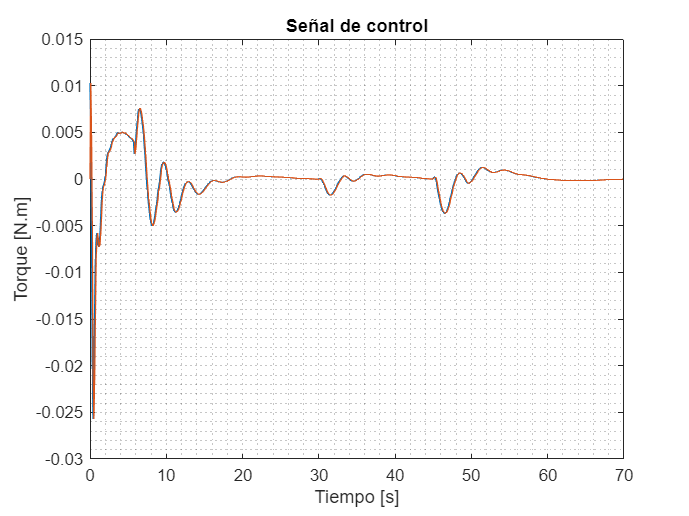


%%%%%%%%
figure
plot(tdisc,control, tdisc,-controlmed);
xlabel('Tiempo [s]');
ylabel('Torque [N.m]');
title('Señal de control')
grid minor;

ITAE y Energía

% Calcular el error
error_signal = ref - estados(:,1);
error_signal2 = 0-estados(:,3);
ITAE = trapz(tdisc, tdisc .* (abs(error_signal)+abs(error_signal2)));
disp(['ITAE: ', num2str(ITAE)]);

ITAE: 0       15.008585        30.01717       45.025753      60.0343399       75.042923       90.051506      105.060089       120.06868      135.077301      150.085846      165.094437      180.103012      195.111572      210.120178      225.128784       240.13736       255.14595      270.154602      285.163147      300.171692      315.180267      330.188873      345.197449      360.206024        375.2146      390.223145      405.231903      420.240356      435.248962      450.257568      465.266144      480.274719      495.283386      510.291901      525.300415      540.309204      555.317688      570.326294      585.335022      600.343384       615.35199      630.360535       645.36908      660.377747      675.386353      690.394897      705.403503      720.412048      735.420654      750.429199      765.437988      780.446289      795.455078      810.463806      825.472351      840.480713      855.489319      870.497925      885.506348      900.515137      915.523621      930.532288 


y = estados(:, 1)*180/pi;
error_signal = abs(ref - y');
ITAE_LQR = trapz(tdisc, tdisc .* (error_signal+error_signal2));
ITAE = sum(tdisc.*error_signal)*Ts;
disp(['ITAE: ', num2str(ITAE)]);

ITAE: 246382.5938



% Calcular de la energía
ene_signal = control.^2;
ENE = trapz(tdisc, tdisc .* abs(ene_signal));
disp(['Energia: ', num2str(ENE)]);

Energia: 0.0022692


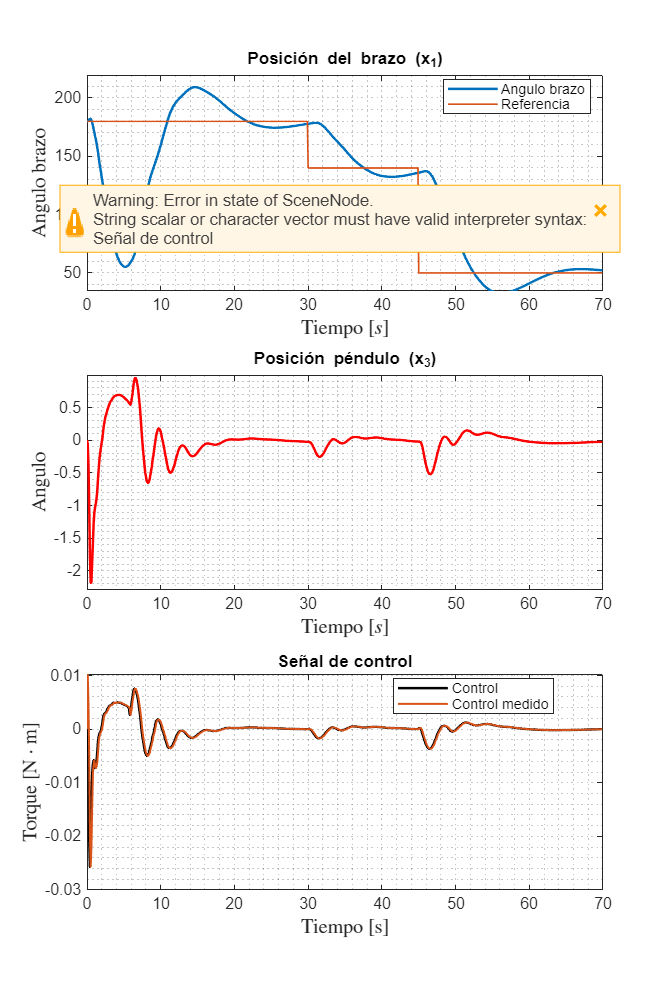

figure('Position', [50, 50, 1200, 1800]);  % [x, y, width, height]

subplot(3,1,1);
plot(tdisc, estados(:,1)*180/pi, 'LineWidth', 1.5);
hold on;
plot(tdisc, re*180/pi, 'LineWidth', 1);
grid minor;
ylabel("Angulo brazo", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
xlabel("Tiempo $[s]$", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
title("Posición del brazo (x_1)");
legend("Angulo brazo", "Referencia", "Location", "best");
xlim([0, Ns*Ts]);
ylim([1.05*min(estados(:,1)*180/pi), 1.05*max(estados(:,1)*180/pi)]);

subplot(3,1,2);
plot(tdisc, estados(:,3)*180/pi, 'r', 'LineWidth', 1.5);
ylabel("Angulo", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
xlabel("Tiempo $[s]$", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
title('Posición péndulo (x_3)')
xlim([0, Ns*Ts])
ylim([1.05*min(estados(:,3)*180/pi), 1.05*max(estados(:,3)*180/pi)])
grid minor;

subplot(3,1,3);
plot(tdisc, control, 'k', 'LineWidth', 1.5); hold on;
plot(tdisc, -controlmed, 'LineWidth', 1.2);
grid minor;
xlabel("Tiempo [s]", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
ylabel("Torque [N$\cdot$m]", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
title("Señal de control", "FontWeight", "bold", "Interpreter", "latex");
legend("Control", "Control medido", "Location", "best");
xlim([0, Ns*Ts]);